## Live Script to Plot Forecasts

Implements the SI-kJalpha method described in the paper: 

*Learning to Forecast and Forecasting to Learn from the COVID-19 Pandemic*

Available at: [https://arxiv.org/abs/2004.11372](https://arxiv.org/abs/2004.11372)

## Load recent data and models for reference day (Mar 21)

We load the recent data available from JHU.

The "reference day" determines the epidmic trends when stay-home orders where not strict. We will reuse this model to forecast what would have

clear;
addpath('./hyper_params');
% Choose 'us' or 'global' below
prefix = 'global';

eval(['load_data_' prefix ';']);


## Load parameters for the reference day


eval(['load ' prefix '_hyperparam_ref_64']);
%
% To change the reference day, run gernerate_scores.m which will train for
% various days. Alternately change '64' to a different number from the
% available mat files. Possibilities are 50, 57, 64, 71, ...


## Identify best hyperparams or use a previously identified set

We also create new variables here to ensure the old hyperparamters do not get overwritten by the new ones


best_param_list_old = best_param_list_no;
MAPEtable_notravel_fixed_old = MAPEtable_notravel_fixed_s;
eval(['load ' prefix '_hyperparam_ref_134']); % Select the day for which we want to use th ehyperparamters for forecasts
best_param_list = best_param_list_no;
MAPEtable_s = MAPEtable_notravel_fixed_s;
best_param_list_no = best_param_list_old;
MAPEtable_notravel_fixed_s = MAPEtable_notravel_fixed_old;

## Train and predict for various scenarios

data_4_s = data_4;
T_tr = 60; % Reference day
T_full = size(data_4_s, 2); % Current day
%T_full = 106; % Choose a different number here to test startign from a past day
horizon = 100; % Number of days in the future

% The following is the list of ratios to simulate out that determine the
% number of true case and number of reported cases
un_array = [1, 2, 5, 10, 20, 40];

for un_id = 1:length(un_array)
    % Train with hyperparams before and after
    un = un_array(un_id); % Select the ratio of true cases to reported cases. 1 for default.
    
    %beta_travel = var_ind_beta_un(data_4_s(:, 1:T_tr), passengerFlow, best_param_list_yes(:, 3)*0.1, best_param_list_yes(:, 1), un, popu, best_param_list_yes(:, 2));
    beta_notravel = var_ind_beta_un(data_4_s(:, 1:T_tr), passengerFlow*0, best_param_list_no(:, 3)*0.1, best_param_list_no(:, 1), un, popu, best_param_list_no(:, 2));
    beta_after = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, best_param_list(:, 3)*0.1, best_param_list(:, 1), un, popu, best_param_list(:, 2));
    
%     alpha_l = MAPEtable_travel_fixed_s(1, 3)*0.1*ones(length(popu), 1);
%     k_l = MAPEtable_travel_fixed_s(1, 1)*ones(length(popu), 1);
%     jp_l = MAPEtable_travel_fixed_s(1, 2)*ones(length(popu), 1);
%     beta_travel_f = var_ind_beta(data_4_s(:, 1:T_tr), passengerFlow, alpha_l, k_l, un, popu, jp_l);
    
    alpha_l = MAPEtable_notravel_fixed_s(1, 3)*0.1*ones(length(popu), 1);
    k_l = MAPEtable_notravel_fixed_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_notravel_fixed_s(1, 2)*ones(length(popu), 1);
    beta_notravel_f = var_ind_beta_un(data_4_s(:, 1:T_tr), passengerFlow*0, alpha_l, k_l, un, popu, jp_l);
    
    alpha_l = MAPEtable_s(1, 3)*0.1*ones(length(popu), 1);
    k_l = MAPEtable_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_s(1, 2)*ones(length(popu), 1);
    beta_after_f = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, alpha_l, k_l, un, popu, jp_l);
    
    disp(['trained for ' num2str(un) 'x']);
    
    % Predict with unreported cases
    
    infec_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_after, popu, best_param_list(:, 1), horizon, best_param_list(:, 2), un);
    infec_released_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_notravel, popu, best_param_list_no(:, 1), horizon, best_param_list_no(:, 2), un);
    
    k_l = MAPEtable_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_s(1, 2)*ones(length(popu), 1);
    infec_f_un = var_simulate_pred_un(data_4(:, 1:T_full), passengerFlow*0, beta_after_f, popu, k_l, horizon, jp_l, un);
    
    k_l = MAPEtable_notravel_fixed_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_notravel_fixed_s(1, 2)*ones(length(popu), 1);
    infec_released_f_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_notravel_f, popu, k_l, horizon, jp_l, un);
    
    
    disp(['predicted for ' num2str(un) 'x'])
    
    eval(['infec_un_' num2str(un) '= infec_un;']);
    eval(['infec_f_un_' num2str(un) '= infec_f_un;']);
    eval(['infec_released_un_' num2str(un) '= infec_released_un;']);
    eval(['infec_released_f_un_' num2str(un) '= infec_released_f_un;']);
end

trained for 1x


predicted for 1x


trained for 2x


predicted for 2x


trained for 5x


predicted for 5x


trained for 10x


predicted for 10x


trained for 20x


predicted for 20x


trained for 40x


predicted for 40x


## Plot Scenario Forecasts

figure('DefaultAxesFontSize',18);
sel_reg = "US"; % Select a region to predict
un = 5;
sel_horizon = 11

sel_horizon = 11

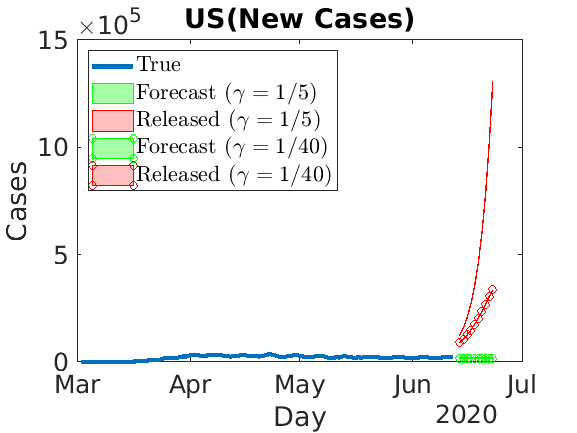

 

xx = find(strcmpi(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx;
end

eval(['infec_un = infec_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_f_un = infec_f_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_released_un = infec_released_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_released_f_un = infec_released_f_un_' num2str(un) '(:, 1:sel_horizon);']);

offset = 40;
trueshow = (offset:size(data_4_s, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(data_4(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 21)+caldays(T_full+1:T_full+size(infec_un, 2));
yy = [infec_un(cid,:)' infec_f_un(cid,:)'];
yy = diff(yy); Tx = Tx(2:end);
%plot(Tx, yy, 'g','LineStyle', 'none', 'Marker', 'o', 'LineWidth', 4, 'MarkerSize', 0.1); hold on;
h = fill([Tx fliplr(Tx)], [yy(:, 1)' fliplr(yy(:, 2)')], 'g', 'LineWidth', 1, 'EdgeColor', 'g');
set(h,'facealpha',.35)


yy = [infec_released_un(cid,:)' infec_released_f_un(cid,:)'];
yy = diff(yy); %Tx = Tx(2:end);
%plot(Tx, yy , 'r', 'LineStyle', 'none', 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 0.1);
h = fill([Tx fliplr(Tx)], [yy(:, 1)' fliplr(yy(:, 2)')], 'r', 'LineWidth', 1, 'EdgeColor', 'r');
set(h,'facealpha',.25)

%
un = 40;
eval(['infec_un = infec_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_f_un = infec_f_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_released_un = infec_released_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_released_f_un = infec_released_f_un_' num2str(un) '(:, 1:sel_horizon);']);


Tx = datetime(2020, 1, 21)+caldays(T_full+1:T_full+size(infec_un, 2));
yy = [infec_un(cid,:)' infec_f_un(cid,:)'];
yy = diff(yy); Tx = Tx(2:end);
%plot(Tx, yy, 'g','LineStyle', 'none', 'Marker', 'o', 'LineWidth', 4, 'MarkerSize', 0.1); hold on;
h = fill([Tx fliplr(Tx)], [yy(:, 1)' fliplr(yy(:, 2)')], 'g', 'LineWidth', 1, 'EdgeColor', 'g', 'Marker', 'o');
set(h,'facealpha',.35)


yy = [infec_released_un(cid,:)' infec_released_f_un(cid,:)'];
yy = diff(yy); %Tx = Tx(2:end);
%plot(Tx, yy , 'r', 'LineStyle', 'none', 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 0.1);
h = fill([Tx fliplr(Tx)], [yy(:, 1)' fliplr(yy(:, 2)')], 'r', 'LineWidth', 1, 'EdgeColor', 'r', 'Marker', 'o');
set(h,'facealpha',.25)
%
title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Cases');
legend({'True', 'Forecast ($\gamma = 1/5$)', 'Released ($\gamma = 1/5$)', 'Forecast ($\gamma = 1/40$)', 'Released ($\gamma = 1/40$)'}, 'Location','northwest', 'Interpreter', 'latex');
%legend({'True', ['Forecast (' num2str(un) 'x )'], ['Released (' num2str(un) 'x )']}, 'Location','northwest');
hold off;